csvFile = "C:/Users/dante/OneDrive/Documentos/UDEM/PEF/ExoRecordings/Recording 18-11-2025 17-52.csv"

csvFile = "C:/Users/dante/OneDrive/Documentos/UDEM/PEF/ExoRecordings/Recording 18-11-2025 17-52.csv"

% Read the CSV file
data = readtable(csvFile);

% Extract the timestamps from the first column
timestamps = data{:, 1};

% Calculate the time differences in seconds
timeDifferences = diff(timestamps)

timeDifferences =     0.0150
    0.0060
    0.0070
    0.0120
    0.0060
    0.0120
    0.0080
    0.0110
    0.0100
    0.0110
    0.0100
    0.0090
    0.0100
    0.0110
    0.0090



% Calculate mean, variance, and standard deviation
meanDiff = mean(timeDifferences);
varDiff = var(timeDifferences);
stdDiff = std(timeDifferences);

% Display the results
fprintf('Tiempo promedio entre muestras: %.3f ms\n', meanDiff*1000);

Tiempo promedio entre muestras: 10.003 ms


fprintf('Varianza: %.3f ms^2\n', varDiff*1000*1000);

Varianza: 2.652 ms^2


fprintf('Desviación Estándar: %.3f ms\n', stdDiff*1000);

Desviación Estándar: 1.629 ms


fprintf('Diferencia mínima: %.3f ms\n',min(timeDifferences)*1000);

Diferencia mínima: 6.000 ms


fprintf('Diferencia máxima: %.3f ms\n',max(timeDifferences)*1000);

Diferencia máxima: 29.000 ms


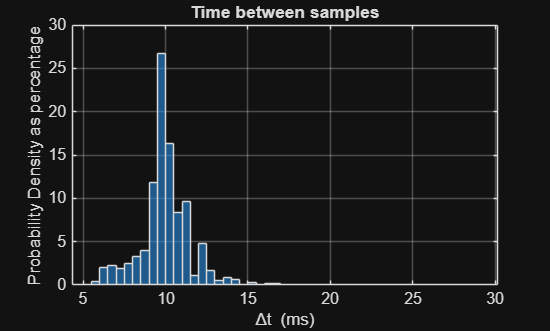


% Create a histogram of the time differences
figure;
histogram(timeDifferences*1000, 'Normalization', 'percentage');
grid on;
title('Time between samples');
xlabel('\Deltat (ms)');
ylabel('Probability Density as percentage');